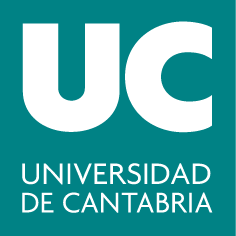

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Métodos Matemáticos en la Ingeniería**

**Bloque II: Métodos Numéricos**

# **5. Optimización**

## Introducción

Llamamos **optimización** al acto de obtener el mejor resultado posible dadas ciertas circunstancias. En matemáticas y ciencias aplicadas, la optimización implica encontrar el valor óptimo de una función en un dominio específico. Este valor puede ser un mínimo o un máximo, dependiendo del problema.

La localización de raíces (Tema 2) y la optimización están relacionadas en el sentido de que ambas involucran la búsqueda de un punto en una función:

- Localización de raíces: Consiste en encontrar los ceros de una función, es decir, los puntos donde la función se anula $( f(x) = 0)$.

- Optimización: Consiste en encontrar el mínimo o el máximo de una función, es decir, los puntos donde la función alcanza sus valores extremos.

#### Programación matemática

Determinar $$x$ $que minimiza (maximiza) $$f(x)$$ sujeto a

		
$$$d_i(x) \leq a_i, \quad i = 1, \ldots, m,$$$


		
$$$e_i(x) = b_i, \quad i = 1, \ldots, p$,$$


donde 

- $$x \in \mathbb{R}^n$$ es un vector de diseño n-dimensional; 

- $$f(x)$$ es la función objetivo; 

- $$d_i(x)$$ son las restricciones de desigualdad; 

- $ $e_i(x)$$ son las restricciones de igualda

- $$a_i$ y $b_i$ $son constantes.

Clasificación de los problemas de programación:

- Si $$f(x)$ $y las restricciones son lineales $$\rightarrow$$ **problema de programación lineal **

- Si $$f(x)$ $es cuadrática y las restricciones son lineales$$\rightarrow$$ **problema de programación cuadrática**

- Si $$f(x)$ $ no es lineal ni cuadrática y/o las restricciones no son lineales $$\rightarrow$$ **problema de programación no lineal**

-  Se dice también que se tiene un **problema de optimización restringido** si se incluyen las restricciones $ $d_i(x)$ y $e_i(x)$$; de otra forma, se trata de un **problema de optimización no restringido**.

**Ejercicio (5.1)**

Clasifica los siguientes problemas de optimización:

- Maximizar $$f(x, y) = 3x + 5y$$ sujeto a: $\begin{cases}
			x + y \leq 10 \\
			x \geq 0, y \geq 0
		\end{cases}$

- Minimizar $$f(x) = x^2 - 4x + 4$$.

- Minimizar $$f(x, y) = (x - 2)^2 + (y - 3)^2$$ sujeto a: $\[ x^2 + y^2 \leq 1 \]$

## Optimización unidimensional

	La función $$f(x)$$ es **unimodal** en el intervalo $$[a,b]$ $si existe el punto $$x^* \in [a,b]$$ tal que $$\forall x_1, x_2 \in [a,b], \; x_1 < x_2$$ se cumple 

- 
$$ $f(x_1) >f (x_2)$, si $x_2<x^*$,$$


- $$f(x_1) < f(x_2)$, si $x*<x_1<x_2$$.

La función se llama  unimodal  en un intervalo, si tiene sólo un extremo en este intervalo.

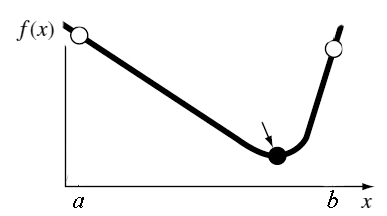

**Resuelve los ejercicios (5.2)-(5.4)**

 % escribe aquí el código





**Métodos de la optimización unidimensional**

- Métodos cerrados (métodos de eliminación de regiones):  Método de bisección (dicotomía), Método de la sección dorada, etc.

- Métodos indirectos: Método de Newton, Método de la secante

-  Métodos de aproximación polinomial

**Métodos cerrados**

Este tipo de métodos se centra en la búsqueda de soluciones óptimas mediante sucesivas reducciones del intervalo de estudio y la eliminación de subintervalos. Si la función es unimodal (tiene un único mínimo o máximo en el intervalo considerado), se puede definir un criterio para eliminar regiones donde el óptimo seguramente no se encuentra. Cuando el subintervalo “sobreviviente” tenga una longitud suficientemente pequeña, la búsqueda termina.

**Ventajas de los Métodos cerrados**

La gran ventaja de estos métodos de búsqueda es que solo requieren evaluaciones de la función y no necesitan ninguna hipótesis adicional acerca de la derivabilidad de la misma. Esto significa que se pueden aplicar a una amplia gama de funciones, incluidas aquellas que no son suaves o que no tienen derivadas continuas.

#### **Método de bisección (dicotomía)**

El método de dicotomía, también conocido como método de bisección, en el contexto de optimización, se utiliza para encontrar el mínimo o máximo de una función unimodal en un intervalo cerrado$ \([a, b]\)$. El método  se basa en reducir el intervalo de búsqueda en cada iteración, dividiéndolo en dos subintervalos y eliminando el subintervalo donde no puede estar el óptimo. El proceso se repite hasta que el intervalo sea suficientemente pequeño.

**Ejercicio (5.5)**

Dada una función $$f(x)$$ que es unimodal y tiene un mínimo en el intervalo $ $[a, b]$$. Si se seleccionan dos puntos $$x_1$ y $x_2$$ dentro del intervalo tal que $$a < x_1 < x_2 < b$$, responde a las siguientes preguntas:

- Si $$f(x_1) < f(x_2)$$, ¿en qué subintervalo se puede asegurar que se encuentra el mínimo?

- Si $$f(x_1) > f(x_2)$$, ¿cuál sería el nuevo intervalo de búsqueda para el mínimo?

- ¿Qué sucede si $$f(x_1) = f(x_2)$$?

**Solución:**

- Si $$f(x_1) < f(x_2)$$, significa que no podemos estar en la región a la izquierda del mínimo donde la función es estrictamente decreciente. Por lo tanto, el mínimo no puede estar a la derecha de $$x_2$$. El nuevo intervalo de búsqueda es $$[a, x_2]$}$. 

- Si $$f(x_1) > f(x_2)$$, la función está decreciendo entre$ $x_1$ y $x_2$$, lo que implica que el mínimo está a la derecha de $$x_1$$. El nuevo intervalo de búsqueda es $\textbf{$[x_1, b]$}$. 

- Si $$f(x_1) = f(x_2)$$, asumiendo que la función es estrictamente unimodal, el mínimo debe encontrarse entre los dos puntos. El nuevo intervalo de búsqueda es $\textbf{$[x_1, x_2]$}$.

**Algoritmo del método de dicotomía**

1.Definir el intervalo inicial $\([a, b]\)$ y una tolerancia $\(\epsilon\)$.

2. En cada iteración, evaluar la función en dos puntos, $\(x_1\) y \(x_2\)$, que están equidistantes del punto medio del intervalo $\([a, b]\)$:


$$    x_1 = \frac{a + b }{2}- \delta, \quad x_2 = \frac{a + b }{2}+ \delta$$


 donde $\(\delta\)$ es una pequeña constante positiva.

3. Reducir del Intervalo:

    - Si $\(f(x_1) < f(x_2)\)$, entonces el mínimo se encuentra en $\([a, x_2]\)$, y se actualiza $ \(b = x_2\)$.

    - Si $\(f(x_1) > f(x_2)\)$, entonces el mínimo se encuentra en $\([x_1, b]\)$, y se actualiza $\(a = x_1\)$.

4. Repetir el proceso hasta que la longitud del intervalo $\([a, b]\)$ sea menor que la tolerancia $\(\epsilon\)$.

**Ejercicio (5.6): **Encontrar el mínimo de la función $\(f(x) = (x-2)^2 + 3\)$ en el intervalo $\([0, 3]\)$ con una tolerancia de $\(10^{-6}\)$.

1.Definir el intervalo inicial $\([a, b]\)$ y una tolerancia $\(\epsilon\)$.

clearvars
close all
f = @(x) (x-2).^2+3;
a = 0; b = 3;
epsilon = 1e-6; 
delta = epsilon/2;
fplot(f,[a,b],'b-')
grid on

La función es unimodal en el itervalo $[a,b]$, entonces, se puede aplicar el método de bisección.

2. Definir dos puntos: $    x_1 = \frac{a + b }{2}- \delta, \quad x_2 = \frac{a + b }{2}+ \delta$

x1 = (a+b)/2-delta; x2 = (a+b)/2+delta;
f1 = f(x1); f2 = f(x2);
fprintf("f(%.4f) = %.8f,\tf(%.4f) = %.8f",x1,f1,x2,f2)

Entonces, en el punto $x = \frac{a+b}{2}$ la función decrece y el mínimo no puede estar en el subintervalo $[a,x_1].$ 

3. Reducir del Intervalo:

a = x1;

4. Repetir el proceso:

x1 = (a+b)/2-delta; x2 = (a+b)/2+delta;
f1 = f(x1); f2 = f(x2);
fprintf("f(%.4f) = %.4f,\tf(%.4f) = %.4f",x1,f1,x2,f2)

Entonces, en el punto $x = \frac{a+b}{2}$ la función crece y el mínimo no puede estar en el subintervalo $[x_2,b].$

b = x2;
x1 = (a+b)/2-delta; x2 = (a+b)/2+delta;
f1 = f(x1); f2 = f(x2);
fprintf("f(%.4f) = %.4f,\tf(%.4f) = %.4f",x1,f1,x2,f2)

... 

Escribimos el algoritmo completo:

clearvars
close all
f = @(x) (x-2).^2+3;
a = 0; b = 3;
epsilon = 1e-6; 
delta = epsilon/2;

while (b - a) / 2 > epsilon
    x1 = (a + b) / 2 - delta;
    x2 = (a + b) / 2 + delta;
    f1 = f(x1);     f2 = f(x2);  
    % Comparar y actualizar el intervalo
    if f1 < f2
        b = x2;
    else
        a = x1;
    end
    l = b-a;
end
xmin = (a + b) / 2;
fmin = f(xmin);  
fplot(f,[a,b],'b-')
grid on
hold on
plot(xmin,fmin,'r*')

#### **Método de la sección dorada**

Este método es una mejora del método de dicotomía y se basa en la propiedad matemática de la proporción áurea. El método de la sección dorada divide el intervalo de búsqueda en segmentos que mantienen una proporción constante, llamada proporción áurea. Esta proporción es aproximadamente $\varphi=\frac{1+\sqrt{5}}{2}\approx1.618$.

Algoritmo:

1. Calcular la razón dorada: $$d = \frac{\sqrt{5}-1}{2}$$ y poner $$\tau = 1-d = \frac{3-\sqrt{5}}{2}$$

2. Elegir dos puntos interiores: $$x_1 = a + \tau(b-a)$$, $$x_2 = a+b-x_1$$

3. Evaluar la función $$f(x)$ $en estos dos puntos.

4. Comparar los valores $$f(x_1)$$ y $$f(x_2)$$:

	- Si$ $f(x_1) \leq f(x_2)$$, poner $$b= x_2$, $x_2 = x_1$, $x_1 = a+b-x_2$$;

	- Si $$f(x_1) > f(x_2)$$, poner $$a= x_1$, $x_1 = x_2$, $x_2 = a+b-x_1$$;

5. Calcular la longitud del intervalo: $$L = b-a$$.

6. Repetir el proceso hasta que $$L<\epsilon$$, 

7. $$x_{opt} = 0.5(a+b)$$.

**Ejercicio (5.7)**: Dada la función $$f(x) = x^4 +2x^3+8x^2+5x$$,  utiliza el método de la sección dorada hallar el mínimo de $$f(x)$$ en el intervalo $$[-2, \, 1]$$ con $\epsilon = 10^{-6}$. ¿Cuántas iteraciones se necesitan?

clearvars
close all
f = @(x)x.^4 +2*x.^3+8*x.^2+5*x;
a = -2; b = 1; tol = 1e-6;

% escribe el código aquí



#### **Métodos indirectos**

**Método de Newton** para $$f(x)= 0$$: $$x_{k+1} = x_k - \frac{f(x_k)}{f'(x_k)}$$

Punto crítico: $$f'(x) = 0$ \rightarrow$ Aplicar el método de Newton para la ecuación$ $f'(x) =0$$:


$$$$x_{k+1} = x_k - \frac{f'(x_k)}{f''(x_k)}$$$$


asegurando que para cada paso $$k$$, $$f(x_{k+1})<f(x_k).$$ 

**Ventajas:** converge cuadráticamente. Para una función cuadrática converge con una iteración.

Desventajas: se deben calcular las derivadas primeras y segundas. Si las derivadas	segundas son nulas el método converge lentamente. 

**Ejercicio (5.11):** Dada la función$ $f(x) = x^4 +2x^3+8x^2+5x$$, hallar el mínimo de $$f(x)$$ en el intervalo $$[-2, \, 1]$$ con $\epsilon = 10^{-6}$.

clearvars
close all
f = @(x) x.^4 +2*x.^3+8*x.^2+5*x;
df = @(x) 4*x.^3 + 6*x.^2 + 16*x+5;
d2f = @(x) 12*x.^2 + 12*x + 16;
a = -2; b = 1; tol = 1e-6;
fplot(f,[a,b],'b-')
grid on

Función es unimodal. Elegimos como la aproximación inicial el punto medio: $x_0 = \frac{a+b}{2}$

x = (a+b)/2;
for k = 1:100
    x1 = x;
    if abs(d2f(x))>eps
        x = x - df(x)/d2f(x);
    else
        disp('diverge!'); break;
    end
    if abs(df(x))<tol || abs(x-x1)<tol
        break;
    end
end
xmin = x;
fmin = f(xmin);
fprintf("x_min = %.4f, f_min = %.4f\n Iteraciones: %d",xmin,fmin,k)

#### **Optimization Toolbox: **`fminbnd`

[`fminbnd`](https://es.mathworks.com/help/matlab/ref/fminbnd.html)`: `Para funciones unidimensionales, MATLAB ofrece la función ``fminbnd`` para encontrar el mínimo de una función en un intervalo dado.

- **fun**: La función que se va a minimizar, definida como un handle de función.

- **x1, x2**: Los límites inferior y superior del intervalo de búsqueda.

- **options**: Una estructura de opciones para personalizar el comportamiento del algoritmo.

- **x**: El punto donde se alcanza el valor mínimo de la función.

- **fval**: El valor de la función en el punto mínimo.

- **exitflag**: Un indicador del estado de salida.

- **output**: Una estructura que contiene información sobre el proceso de optimización.

La función `fminbnd` permite ajustar varias opciones de optimización mediante la función `optimset`. Algunas opciones comunes incluyen:

- **TolX**: La tolerancia en el valor de xxx.

- **MaxIter**: El número máximo de iteraciones.

- **MaxFunEvals**: El número máximo de evaluaciones de la función.

Ejemplo: Volvemos a resolver Ejercicio (5.11) utilizando el comando `fminbnd:`

clearvars
close all
f = @(x)x.^4 +2*x.^3+8*x.^2+5*x;
a = -2; b = 1;
options = optimset('TolX',1e-6)
[x,fval,exitflag,output] = fminbnd(f,a,b,options)

## **Optimización multidimensional**

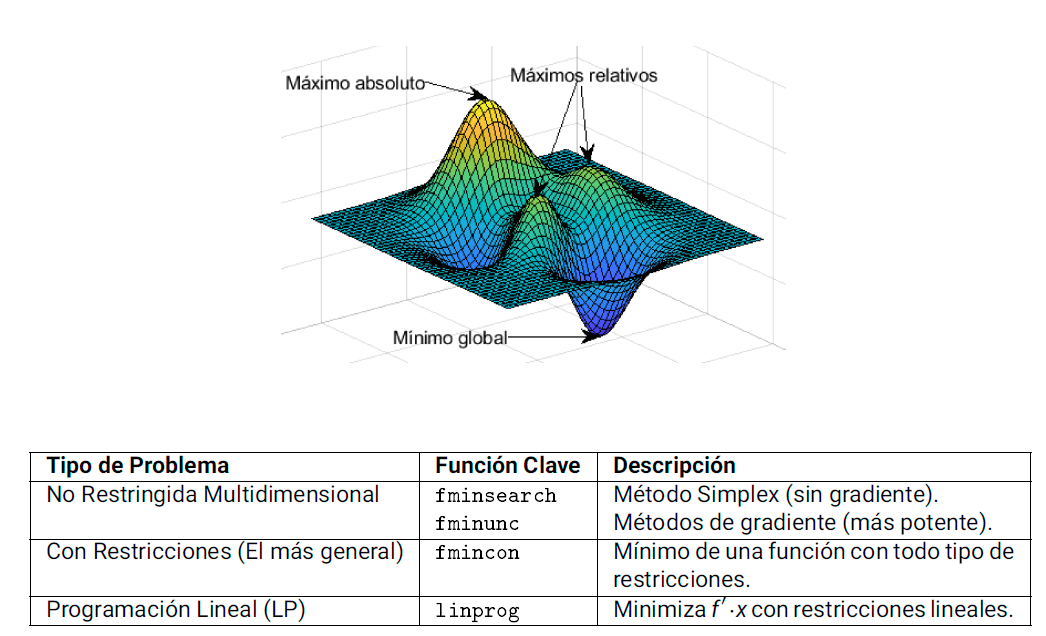

#### [`fminsearch`](https://es.mathworks.com/help/matlab/ref/fminsearch.html)

Busca el mínimo local de un problema especificado por $\min_xf (x)$

*f*(*x*) es una función que devuelve un escalar y *x* es un vector o un arreglo.

**Sintaxis:**

**Ejercicio (5.13) **

clearvars
f = @(x) x(1)^3 - 6*x(1)*x(2) + 3*x(2)^2 - 1;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
xopt = fminsearch(f,[1,1],options)

#### [`fminunc`](https://www.mathworks.com/help/optim/ug/fminunc.html)

Busca el mínimo de un problema especificado por $\min_xf (x)$

*f*(*x*) es una función que devuelve un escalar y *x* es un vector o un arreglo.

**Sintaxis:**

**Ejercicio (5.13) **

clearvars
f = @(x) x(1)^3 - 6*x(1)*x(2) + 3*x(2)^2 - 1;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
xopt = fminunc(f,[1,1],options)

#### [`fmincon`](https://es.mathworks.com/help/optim/ug/fmincon.html)

Solver de programación no lineal.

Encuentra el mínimo de un problema especificado por

Minimizar $$f(x)$$ sujeto a: $\begin{cases}
			A \cdot x &\le b \\
			A_{eq} \cdot x &= b_{eq} \\
			lb \le x &\le ub \\
			c(x) &\le 0 \\
			c_{eq}(x) &= 0
		\end{cases}$

*b* y *beq* son vectores, *A* y *Aeq* son matrices, *c*(*x*) y *ceq*(*x*) son funciones que devuelven matrices, y *f*(*x*) es una función que devuelve un escalar. *f*(*x*), *c*(*x*) y *ceq*(*x*) pueden ser funciones no lineales.

*x*, *lb* y *ub* se pueden pasar como vectores o matrices.

Sintaxis:

**Ejercicio (5.14)**

Clasifica el problema y elige el método apropiado para resolverlo:

a) Minimizar la función $$f(x, y) = (x-2)^2 + 2(y-1)^2$$ partiendo del punto inicial $$(x_0, y_0) = (0, 0)$$.

% escribe aquí el código:



b) Maximizar la función $\( f(x, y) = 2xy + 2x - x^2 - 2y^2 \) $usando los valores iniciales, $\( x = -1 \), \( y = 1 \)$.

% escribe aquí el código:



c) Minimizar $$f(x, y) = (x - 2)^2 + (y - 3)^2$$ sujeto a: $	\[ x^2 + y^2 \leq 1 \]$

 Optimización restringida no lineal (PPNL). 

fun = @(x) (x(1)-2)^2 + (x(2)-3)^2; 
x0 = [0, 0]; 
nonlcon = @(x) deal(x(1)^2 + x(2)^2 - 1, []);
[x, fval] = fmincon(fun, x0, [],[],[],[],[],[],nonlcon)

d)  Maximizar $$f(x, y) = 3x + 5y$$ sujeto a: $\[
 	\begin{cases}
 		x + y \leq 10 \\
 		x \geq 0, y \geq 0
 	\end{cases}
 	\]$

% escribe aquí el código:



## **Programación lineal**

Dado el problema:

	
$$$\min_x f^Tx$

	$Ax \leq b$, 
	
	$A_ex = b_e$,
	
	$a \leq x \leq  b$ $$


La función [`linprog`](https://es.mathworks.com/help/optim/ug/linprog.html) en MATLAB se utiliza para resolver problemas de programación lineal, donde el objetivo es minimizar una función lineal sujeta a restricciones lineales. Es ampliamente utilizada en optimización y en diversas aplicaciones industriales y científicas.

Argumentos de entrada: 

- `f`: Vector de coeficiente, especificado como un vector real o una matriz real.

- `A`: Restricciones de desigualdad lineales, especificadas como una matriz real.

- `b`: Restricciones de desigualdad lineales, especificadas como un vector real. 

- `Aeq`: Restricciones de igualdad lineales, especificadas como una matriz real. 

- `beq`: Restricciones de igualdad lineales, especificadas como un vector real.

- `lb`: Límites inferiores.

- `ub`: Límites superiores.

- `options`: Estructura de opciones como devuelta por `optimoptionsoptimset`.

`linprog `siempre minimiza. Para maximizar una función $$f$$, se debe minimizar $$-f$$.

**Ejercicio (5.15): **$$f(x,y)=5x+4y \to \max$, sujeto a $\begin{cases}
60x+70y &\leq 4000  \\
20x+10y &\leq 800 \\
y&\geq 10  \\
x& \geq 0
\end{cases}
$$

Solución:

Vector de los coeficientes de la función objetivo ( $f(x,y)=5x+4y \to \max$) es -[5, 4]

clearvars
f = -[5 4]; % -> max

Matriz  A y vector b de  restricciones de desigualdad lineales:

A = [60 70; 20 10];
b = [4000; 800];

Las restricciones $x \geq 0, \quad y\geq 10
$  se escriben como

lb = [0, 10];

Como no hay restricciones de igualdad:

Aeq = [];
beq = [];

Llamamos el comando linprog:

X = linprog(f,A,b,Aeq,beq,lb)
Max = -f*X

**Ejercicio (5.18)**: 	Un herrero con 80 kg de acero y 120 kg de aluminio quiere hacer bicicletas de paseo y de montaña que quiere vender, respectivamente a 250 y 450 euros cada una para sacar el máximo beneficio. Para la de paseo empleará 1 kg de acero y 3 kg de aluminio, y para la de montaña 2 kg de ambos metales. ¿Cuántas bicicletas de paseo y de montaña deberá fabricar para maximizar las utilidades?


$$$$\begin{cases}
	f(x,y)  =250x + 450y \rightarrow \max
	\\
	x+2y \leq 80\\
	3x+2y \leq 120\\
	x,y \geq 0
\end{cases}$$$$


linprog resuelve los problemas de minimización, por lo tanto cambiamos el signo en la función objetivo:

f = -[250 450];
A = [1 2; 3 2];
b = [80 120];
Aeq = []; beq=[];
lb = [0; 0;];
linprog(f,A,b,Aeq,beq,lb)

## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulo 13-16)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulo 9)